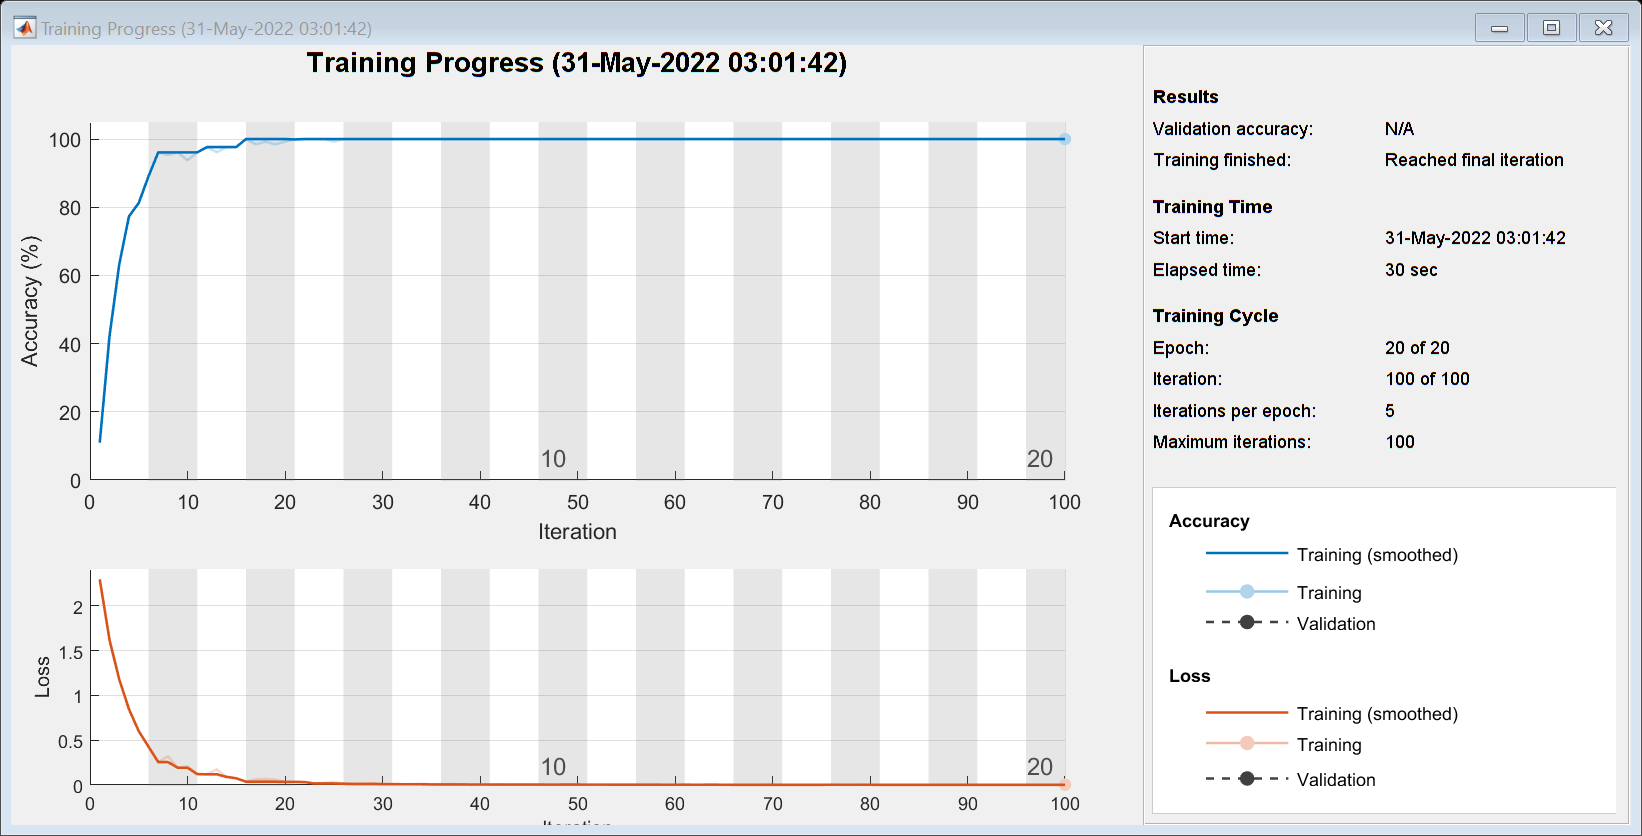

matlabpath = 'C:\Users\bikhi_27b5q2u\Desktop\Предметы\4 курс\8 семестр\Интеллектуальные системы\Цифры';
data = fullfile(matlabpath);
data = imageDatastore(data,'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[dataTrain,dataTest] = splitEachLabel(data,0.9,'randomized');
count = dataTrain.countEachLabel;

% testpath = 'C:\Users\bikhi_27b5q2u\Desktop\Предметы\4 курс\8 семестр\Интеллектуальные системы\Тестовая выборка\';
% dataTest = fullfile(testpath);
% dataTest = imageDatastore(dataTest, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

%figure
%numImages = length(data.Files);
%perm = randperm(numImages,25);
%for i = 1:25
%    subplot(5,5,i);
%    imshow(data.Files{perm(i)});
%    drawnow
%end

imageAugmenter = imageDataAugmenter(...
    'RandRotation',[-20 20],...
    'RandXTranslation',[-3 3],...
    'RandYTranslation',[-3 3]);
imageSize = [32 32 3];
[XTrain,~,YTrain] = digitTrain4DArrayData;
augimds = augmentedImageDatastore(imageSize,XTrain,YTrain,'DataAugmentation',imageAugmenter);

layers = [
	imageInputLayer(imageSize)
    
    convolution2dLayer(3,8,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,32,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,64,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,128,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,256,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(8)
    softmaxLayer
    classificationLayer];

opts = trainingOptions('sgdm',...
    'MaxEpochs',20,...
    'Plots',"training-progress",...
    'Verbose',false, ...
    'Shuffle',"every-epoch");

net = trainNetwork(dataTrain,layers,opts);


% a = imread('C:\Users\bikhi_27b5q2u\Desktop\Предметы\4 курс\8 семестр\Интеллектуальные системы\Тестовая выборка\4\4.08.png')
% out = classify(net,a)
% figure,imshow(a)
% title(string(out))
% msgbox(string(out))

TP(10,1) = 0;
TN(10,1) = 0;
FP(10,1) = 0;
FN(10,1) = 0;
%accuracy(10,1) = 0;
FAR(10,1) = 0;
FRR(10,1) = 0;

allclass=[]


allclass =

     []



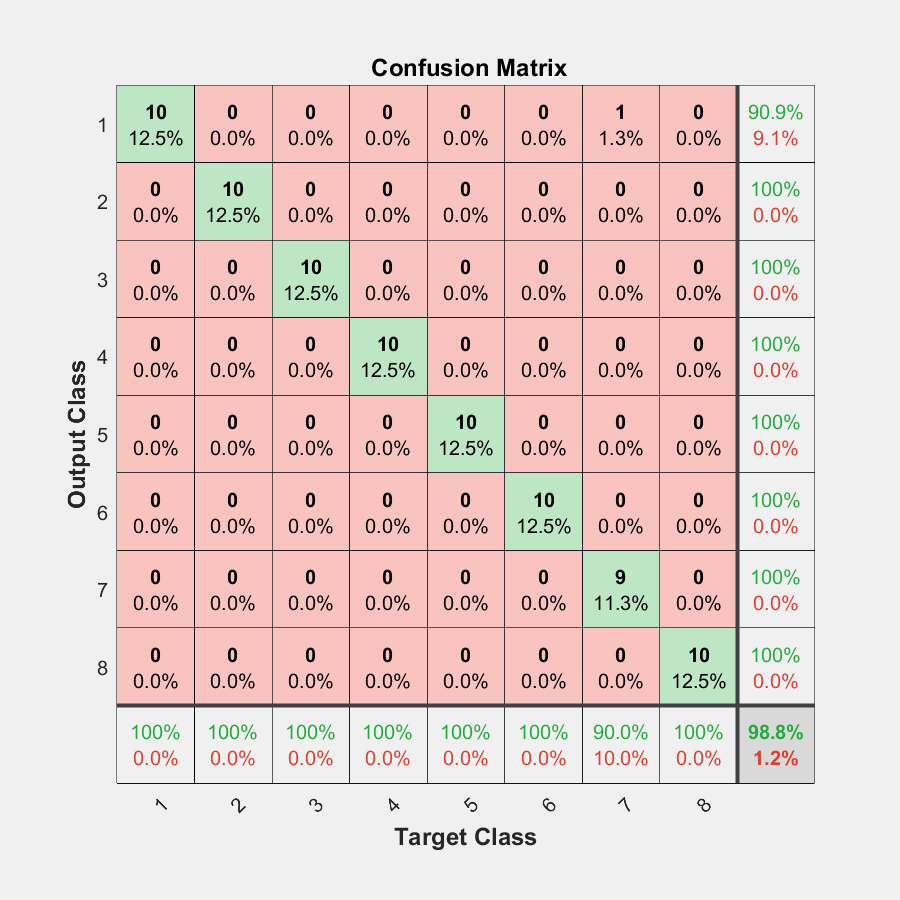

for iii = 1:length(dataTest.Labels)
    I = readimage(dataTest,iii);
    Label = dataTest.Labels(iii);
    class = classify(net,I);
    k = int16(class);
    if (Label == class)
        TP(k,1) = TP(k,1) + 1;
    elseif(Label ~= class)
        FP(int16(class),1) = FP(int16(class),1) + 1;
        FN(int16(Label),1) = FN(int16(Label),1) + 1;
    end
    allclass = [allclass class];
end

Predicted = allclass;
figure,plotconfusion(dataTest.Labels,Predicted')


for l = 1:k
    TN(l,1) = length(dataTest.Labels) - (TP(l,1) + FP(l,1) + FN(l,1));
    %accuracy(l,1) = (TP(l,1) + TN(l,1))/(length(dataTest.Labels));
    FAR(l,1) = FP(l,1)/(FP(l,1) + TN(l,1));
    FRR(l,1) = FN(l,1)/(FN(l,1) + TP(l,1));
end